noise_powers = 1 : 5;
noise_powers = 1e-16 * noise_powers;
tau = 1.0e-03 * [0.3638 0.2513 0.3749 0.4998 0.7877];
tau = 1.0e-03 * [0.5152 0.6179 0.9993 0.8001 0.8938];
reps = 5;

f_sampling = 2e9; % Hz
t_end = 0.01; % secs

t_step = 1/f_sampling;
t = 0 : t_step : t_end;

%% constants
c = 3e8; % m/s
h_eV = 4.136e-15; % eV
k_B = 1.38065e-23; % m2 kg s-2 K-1
h = 6.62607015e-34; % m2 kg / s
hbar_times_c = 2e-7; % eV m

%% parameters
axion_rest_energy = 2e-6; % eV/c2
axion_velocity = 220e3; % m/s
T = 10e-3; % K
axion_power = 1e-21; % W, from eq 2.28 of Daw thesis

% noise powers 1e-16 2e-16

%% axion signal params
f_0 = axion_rest_energy / h_eV; % Hz, default axion frequency
axion_linewidth = f_0 * 0.5 * (axion_velocity / c)^2;
axion_Q = f_0 / axion_linewidth;
de_broglie_wavelength = 2*pi * hbar_times_c / (axion_rest_energy * axion_velocity/c);
t_coherence = de_broglie_wavelength / axion_velocity;

noise_powers = linspace(0.1, 10, 5);
noise_powers = 1e-16 * noise_powers;

tau = [0.0002 0.0006 0.0010 0.0012 0.0025];
reps = 100;

imp_res = zeros([length(noise_powers), reps]);
L = length(noise_powers);
%done = 0

parfor rep = 1 : reps
    %rep
    %% generate axion frequency
    f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_0, axion_linewidth);
    
    %% generate signal and noise
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power);
    noise = randn(size(t)); % don't need to scale here, we do that in improvement()

    for i = 1 : L
        imp_res(i, rep) = imp(tau(i), noise_powers(i), f_sampling, t, signal, noise, f_0, f_axion);
        %done = done+1;
        %disp(round(done/(L*reps)*100)), '%')
        
    end
end

x = axion_power ./ noise_powers;
y = mean(imp_res, 2); % 2nd dimension of imp_res
x = x(2:end);
y = y(2:end);

err = std(imp_res, 0, 2);
err = err(2:end)

err =     4.1300
    2.1529
    1.4485
    0.9511


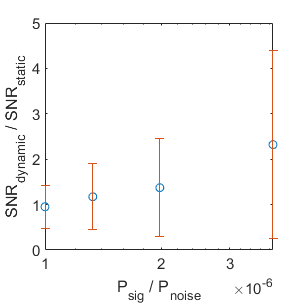


%set(0,'defaulttextinterpreter','latex')
figure

scatter(x, y)
adstyle(8, 8)
hold on
errorbar(x, y, err/2, 'LineStyle','none'); % err/2 cause matlab is silly, check the docs
xlabel('P_{sig} / P_{noise}')
ylabel('SNR_{dynamic} / SNR_{static}')
set(gca,'xscale','log')

saveas(gcf,'figures/results.eps','epsc')

function improvement = imp(tau, noise_power, f_sampling, t, signal, noise_in, f_0, f_axion)

    noise = noise_in * sqrt(noise_power);
    noise_pwr = bandpower(noise);
    
    % atm we're running iwave on the signal not the signal + noise
    iwave_input = signal + noise;
    
    band_width = 150;
    band = [f_0-band_width/2, f_0+band_width/2];
    iwave_input = bandpass(iwave_input, band, f_sampling);
    
    f_iwave = run_iwave(iwave_input, f_sampling, f_0, tau);
    
    % front to chop off
    start_secs = t(end)/4;
    start = start_secs * f_sampling;
    assert(start_secs < t(end)/3)
    
    improvement = get_improvement(signal(start:end), noise(start:end), f_0, f_sampling, f_axion(start:end), f_iwave(start:end), t(start:end));
end